Initializing variables

clear all; close all; clc
load('out_MatRANS.mat');

% Creates the Uf field in MatRANS if it doesn't exists
% Spoiler alert: It does and this block does nothing
if ~isfield(MatRANS, 'Uf')
    MatRANS.Uf = sqrt(MatRANS.tau0/MatRANS.rho)
end

% Constants
nu = 1e-6; % Fluid kinematic viscosity (m^2/s)
beta = 9/100;

%import values from MatRANS
flow.y = MatRANS.y;
flow.h = flow.y(end);
% Take only last time step from time series data
flow.u_mean = MatRANS.u(end,:);
flow.k = MatRANS.k(end,:); %turbulent kinetic energy
% k(1) = 10e-4;
flow.omega = MatRANS.omega(end,:);
flow.Uf = MatRANS.Uf(end);

% Secondary Constants
flow.l = (beta^(-1/4)).*(sqrt(flow.k)./flow.omega);
%flow.v_prime_ms = 1./(3.*flow.k);
flow.v_prime_ms = flow.k ./ 3;
flow.Dt = flow.l ./ sqrt(flow.v_prime_ms);

% Non-dimensionalization
flow.U_mean = flow.u_mean ./ flow.Uf;
flow.DT = flow.Dt .* (flow.Uf/flow.h);
flow.Y = flow.y / flow.h;
flow.V_prime_ms = flow.v_prime_ms ./ flow.Uf;

flow.Y_bottom = 70*nu/flow.Uf/flow.h;

Find an appropriate number of particles

fig1 = figure("Name", "X_mean vs N_particles")

fig1 =   Figure (1: X_mean vs N_particles) with properties:

      Number: 1
        Name: 'X_mean vs N_particles'
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


xlabel('N_(particles)');
ylabel('X_(mean)');
hold on

fig2 = figure("Name", "X_variance vs N_particles")

fig2 =   Figure (2: X_variance vs N_particles) with properties:

      Number: 2
        Name: 'X_variance vs N_particles'
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


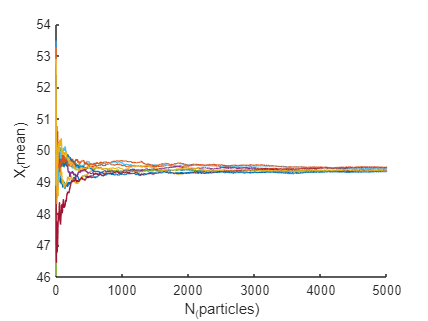

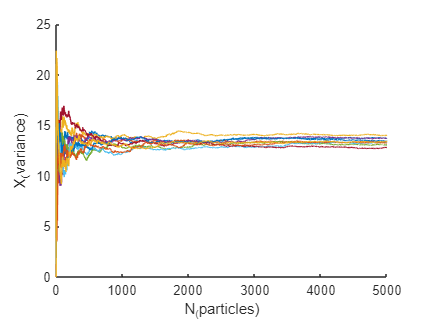

Exp_no = 1

Exp_no = 2

Exp_no = 3

Exp_no = 4

Exp_no = 5

Exp_no = 6

Exp_no = 7

Exp_no = 8

Exp_no = 9

Exp_no = 10

xlabel('N_(particles)');
ylabel('X_(variance)');
hold on

for Exp_no = 1:10
    Exp_no
    N_particles_max = 5000;
    X_10 = zeros(N_particles_max, 1);
    for i_particle = 1:N_particles_max
        particle.X_line = zeros();
        particle.Y_line = zeros();
        
        % Initizalize particle parameters at T=0
        particle.T = 0;
        particle.X = 0;
        particle.Y = (flow.Y_bottom + (flow.Y(end) - flow.Y_bottom)*rand);
        particle.U_p = 0;
        
        found = false;
        particle.closest_temporal_distance = Inf;
        max_DT = max(flow.DT);
        search_window = max_DT * 1.1;
        
        while particle.T <= 10
            if ~found && particle.T >= 10 - search_window % Practically we only need to start checking when its close 
                particle.temporal_distance = abs(10 - particle.T);
                if particle.temporal_distance < particle.closest_temporal_distance
                    X_10(i_particle) = particle.X;
                    particle.closest_temporal_distance = particle.temporal_distance;
                elseif X_10(i_particle) ~= 0
                    found = true;
                end
            end
    
            % Generate random value 
            a_r = randn;
            
            % Find flow parameters at particle Depth
            particle.DT = interp1(flow.Y, flow.DT, particle.Y);  
            particle.V_ms = interp1(flow.Y, flow.V_prime_ms, particle.Y);
            
            particle.DY = a_r .* sqrt(particle.V_ms) .* particle.DT;
            
            % Ensure particle stays within boundary
            particle.Y_next = particle.Y + particle.DY;
            if particle.Y_next > flow.Y(end)
                particle.Y_next = flow.Y(end) - (particle.Y_next - flow.Y(end));
            elseif particle.Y_next < flow.Y_bottom
                particle.Y_next = flow.Y_bottom - (particle.Y_next - flow.Y_bottom);
            end
            
            particle.U_p_next = (particle.U_p + interp1(flow.Y, flow.U_mean, particle.Y_next)) / 2;
            particle.DX = ((particle.U_p + particle.U_p_next)/2)*particle.DT;
            particle.X_next = particle.X + particle.DX;
            
            particle.T = particle.T + particle.DT;
            particle.X = particle.X_next;
            particle.Y = particle.Y_next;
        end
    end
    X_10_mean_line = zeros(1, N_particles_max);
    X_10_mean_variance_line = zeros(1, N_particles_max);
    for N_particles = 1:1:N_particles_max
        X_10_mean = mean(X_10(1:N_particles));
        X_10_mean_line(N_particles) = X_10_mean;
        
        X_10_mean_variance = mean((X_10(1:N_particles) - X_10_mean).^2);
        X_10_mean_variance_line(N_particles) = X_10_mean_variance;
    end
        figure(fig1)
        plot(1:1:N_particles_max, X_10_mean_line, '-')
        figure(fig2)
        plot(1:1:N_particles_max, X_10_mean_variance_line, '-')
end

Actual run

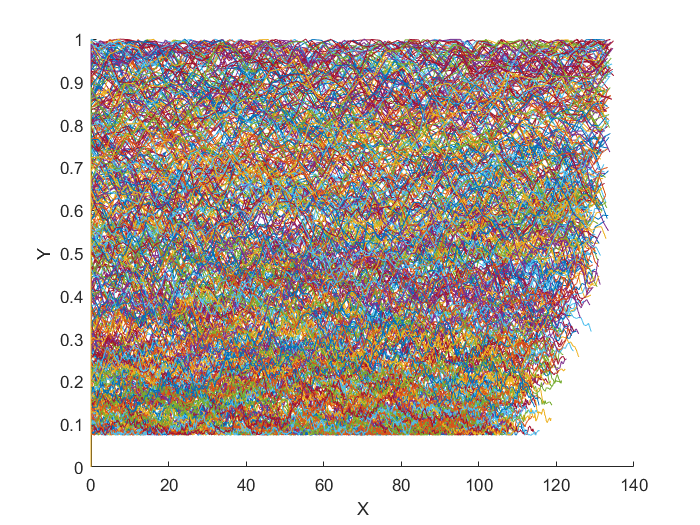

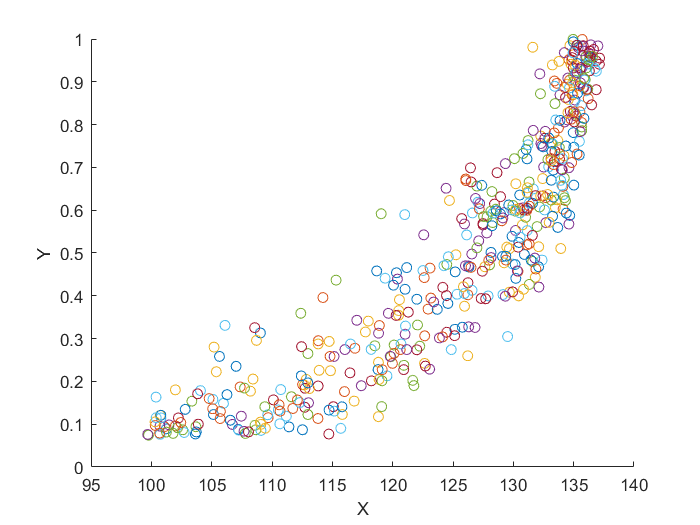

f1 = figure('Name', "Particle Trails");
xlabel('X');
ylabel('Y');
hold on

f2 = figure('Name', "Diffusion Cloud");
xlabel('X');
ylabel('Y');
hold on



N_particles = 500;

times = 5:5:25;
X_record = zeros(size(times, 2), N_particles);
max_DT = max(flow.DT);
search_window = max_DT * 1.1;

for i_particle = 1:N_particles
    particle.X_line = zeros();
    particle.Y_line = zeros();
    
    % Initizalize particle parameters at T=0
    particle.T = 0;
    particle.X = 0;
    particle.Y = (flow.Y_bottom + (flow.Y(end) - flow.Y_bottom)*rand);
    particle.U_p = 0;
    
    found = 0;
    particle.closest_temporal_distance = Inf;
    
    while particle.T < 25
        particle.X_line = [particle.X_line, particle.X];
        particle.Y_line = [particle.Y_line, particle.Y];
        
        if particle.T >= times(found+1) - search_window
            particle.temporal_distance = abs(times(found+1) - particle.T);
            if particle.temporal_distance < particle.closest_temporal_distance
                X_record(found+1, i_particle) = particle.X;
                particle.closest_temporal_distance = particle.temporal_distance;
            elseif X_record(found+1, i_particle) ~= 0
                particle.closest_temporal_distance = Inf;
                found = found + 1;
            end
        end 
        


        % Generate random value 
        a_r = randn;
        
        % Find flow parameters at particle Depth
        particle.DT = interp1(flow.Y, flow.DT, particle.Y);  
        particle.V_ms = interp1(flow.Y, flow.V_prime_ms, particle.Y);
        
        particle.DY = a_r .* sqrt(particle.V_ms) .* particle.DT;
        
        % Ensure particle stays within boundary
        particle.Y_next = particle.Y + particle.DY;
        if particle.Y_next > flow.Y(end)
            particle.Y_next = flow.Y(end) - (particle.Y_next - flow.Y(end));
        elseif particle.Y_next < flow.Y_bottom
            particle.Y_next = flow.Y_bottom - (particle.Y_next - flow.Y_bottom);
        end
        
        particle.U_p_next = (particle.U_p + interp1(flow.Y, flow.U_mean, particle.Y_next)) / 2;
        particle.DX = ((particle.U_p + particle.U_p_next)/2)*particle.DT;
        particle.X_next = particle.X + particle.DX;
        
        particle.T = particle.T + particle.DT;
        particle.X = particle.X_next;
        particle.Y = particle.Y_next;
    end
    figure(f1);
    plot(particle.X_line, particle.Y_line,'-');
    
    figure(f2);
    plot(particle.X, particle.Y,'o');
end


X_mean_line = zeros(1, size(times,2));
X_mean_variance_line = zeros(1, size(times,2));
for i_time = 1:size(times,2)
    X_mean = mean(X_record(i_time, :));
    X_mean_line(i_time) = X_mean;
    X_mean_variance_line(i_time) = mean((X_record(i_time)-X_mean).^2);
end

f3 = figure("Name", "X_mean vs T")

f3 =   Figure (54: X_mean vs T) with properties:

      Number: 54
        Name: 'X_mean vs T'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


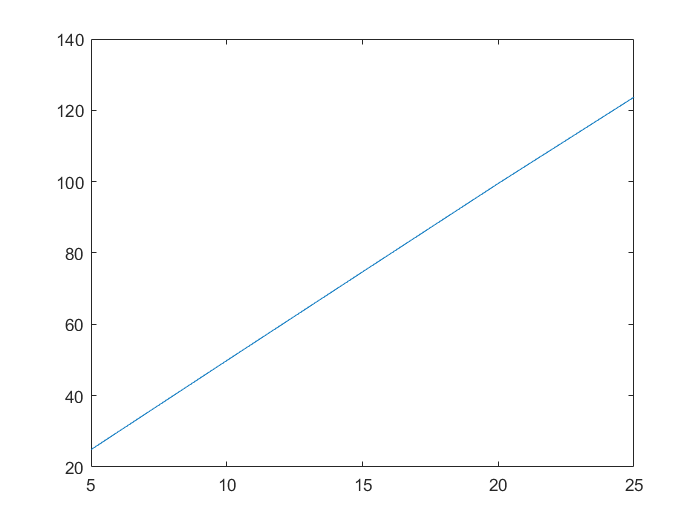

xlabel('T');
ylabel('X_(mean)');
plot(times, X_mean_line, '-')


f4 = figure("Name", "X_mean_variance vs T")

f4 =   Figure (55: X_mean_variance vs T) with properties:

      Number: 55
        Name: 'X_mean_variance vs T'
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


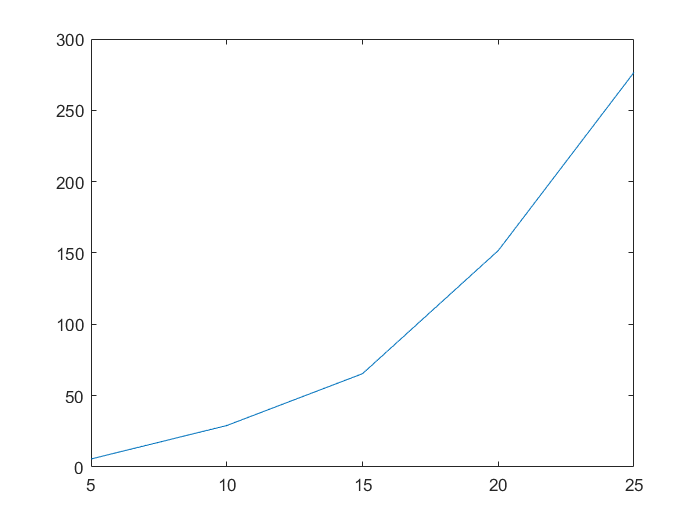

xlabel('T');
ylabel('X_(mean variance)');
plot(times, X_mean_variance_line, '-')